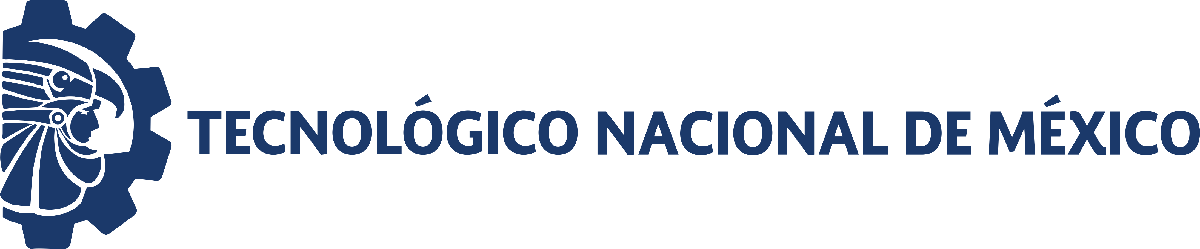                                 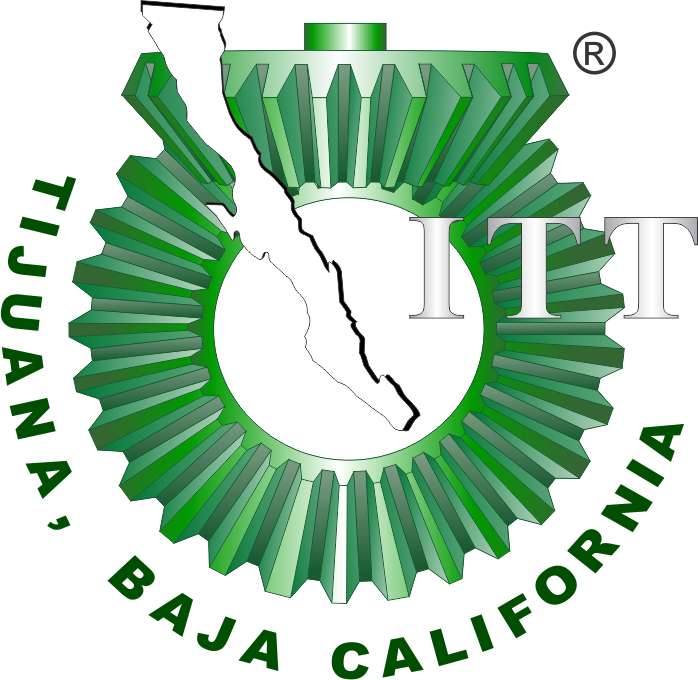

# Práctica 3: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                     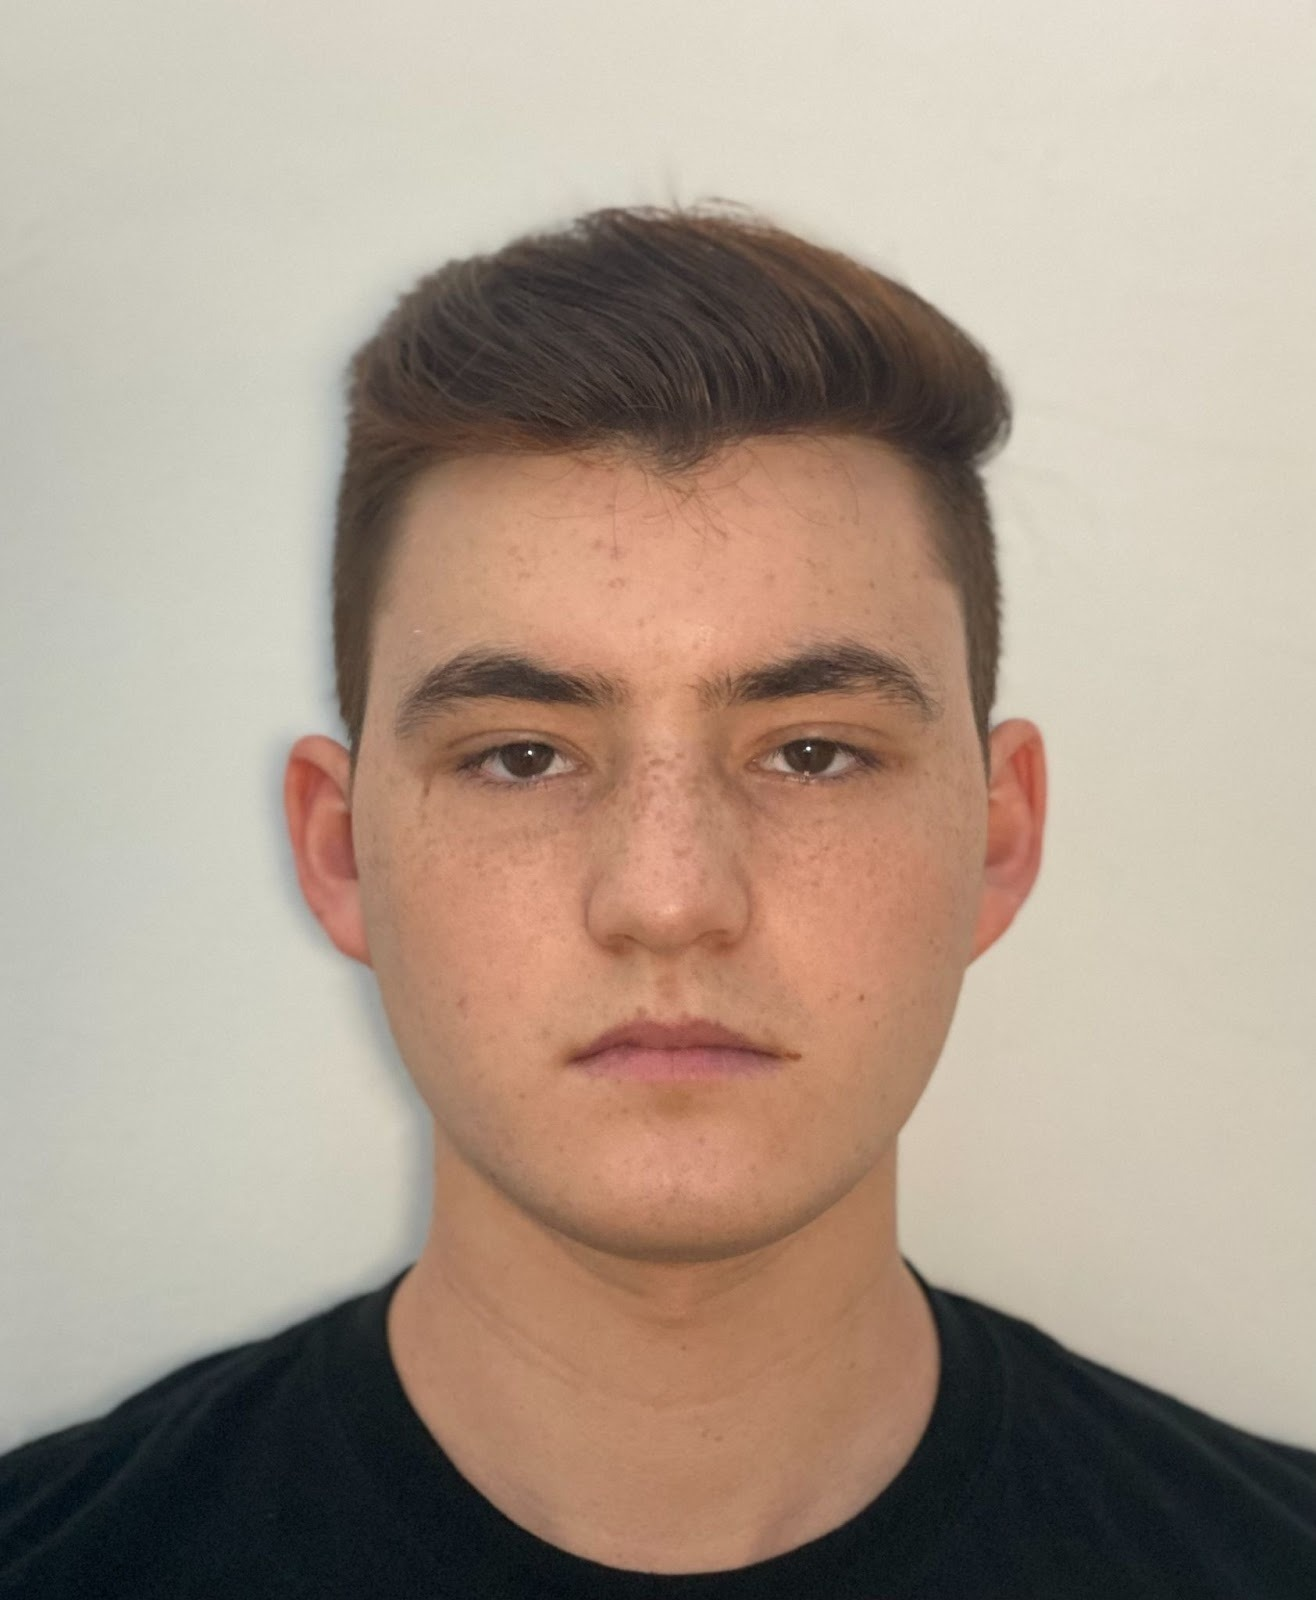

Nombre del alumno: Marco Antonio Campoy Alegria

Número de control: 21212145

Correo institucional: L21212145@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep = '1E-3';
x = sim(file,parameter);


## Respuesta del sistema

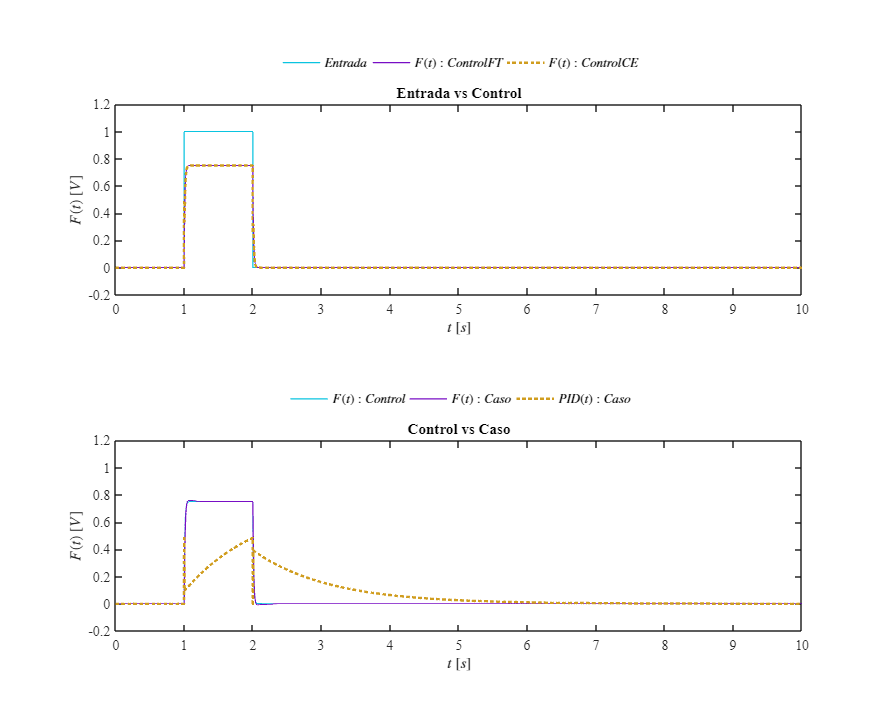

plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,x.PID1)

## Funcion de las señales

function plotsignals(t,F,Fs1,Fs2,Fs3,PID)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,25,20])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
powerrangers = [10,196,224;
120,14,197;
208,157,31]/255;
colororder(powerrangers)
subplot(2,1,1);box on; hold on;

P = plot(t,F,'-',t,Fs1,'-',t,Fs2,':','LineWidth',1); set (P(3),'LineWidth',2)
L = legend('$Entrada$','$F(t):Control FT$','$F(t):Control CE$');
set(L,'Interpreter','Latex','FontSize',10,'location',...
'NorthOutside','box','off','Orientation','Horizontal')
xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$F(t)$ $[V]$','Interpreter','Latex','FontSize',11)
xlim([0,10]); xticks(0:1:10);
ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
T = title("Entrada vs Control"); set(T,'FontSize',10);
set(gca,'FontName','Time News Roman','FontSize',11);
subplot(2,1,2);box on; hold on;
P = plot(t,Fs1,'-',t,Fs3,'-',t,PID,':','LineWidth',1); set (P(3),'LineWidth',2)
L = legend('$F(t):Control$','$F(t):Caso$','$PID(t):Caso$');
set(L,'Interpreter','Latex','FontSize',10,'location',...
'NorthOutside','box','off','Orientation','Horizontal')
xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$F(t)$ $[V]$','Interpreter','Latex','FontSize',11)
xlim([0,10]); xticks(0:1:10);
ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
T = title("Control vs Caso"); set(T,'FontSize',10);
set(gca,'FontName','Time News Roman','FontSize',11)

exportgraphics(gcf,'Musculoesqueletico.pdf','ContentType','vector')
%exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
%print(Signal,'-dsvg','-r600');
%print(Signal,'-depsc','-r600')
end